# ICE

## rice

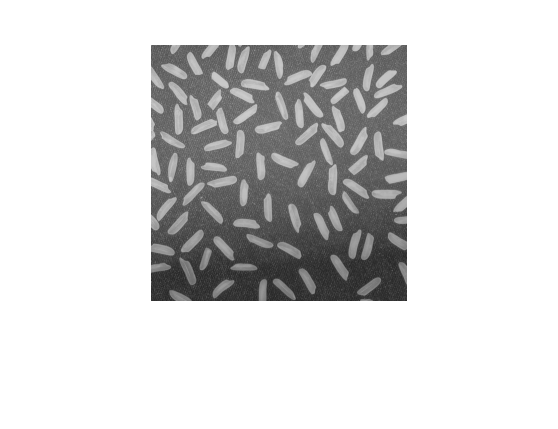

clear all; clc;

I = imread('./imdata/rice.png');
imshow(I);

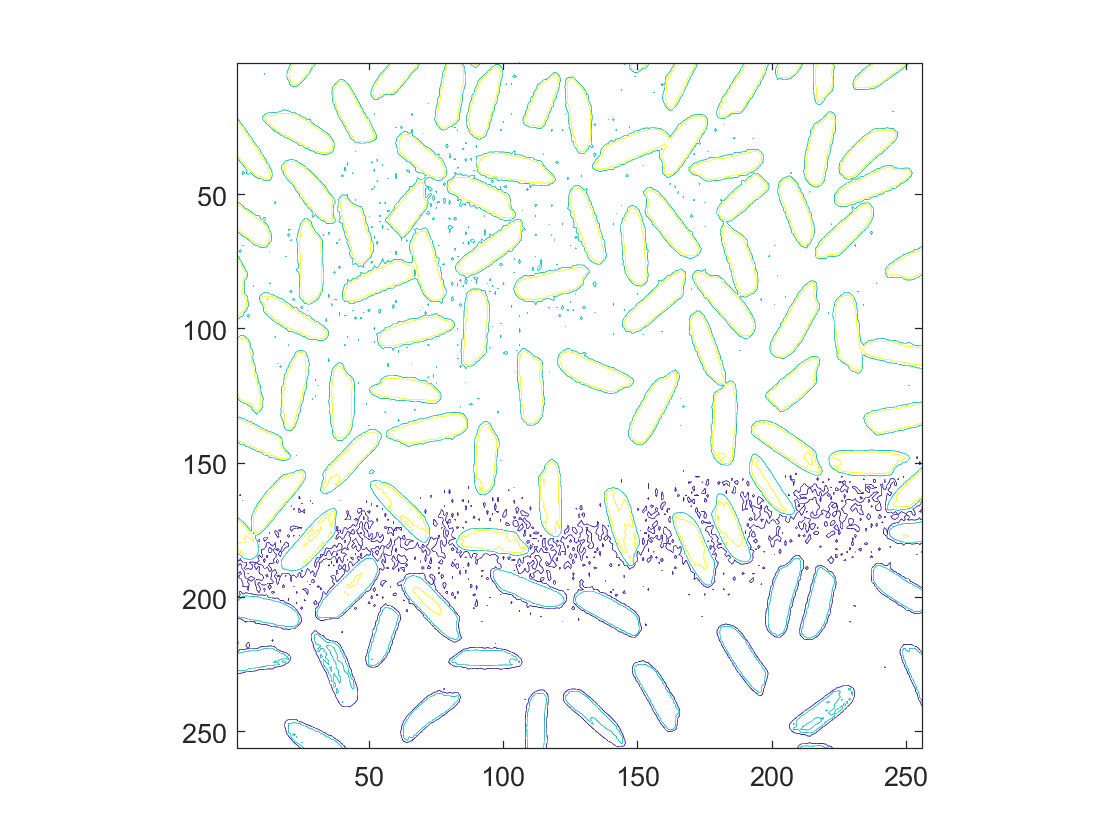


figure; 
imcontour(I,3);

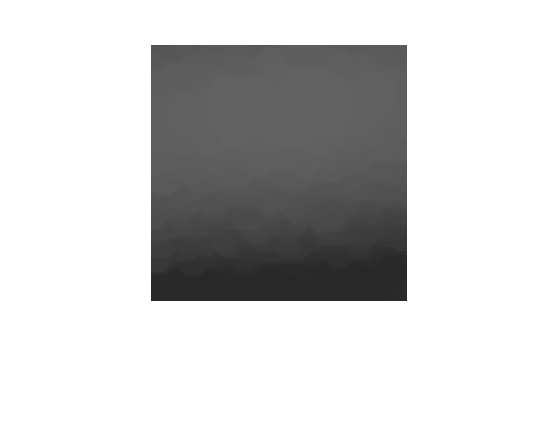


se = strel('disk',15);
background = imopen(I,se);
imshow(background);

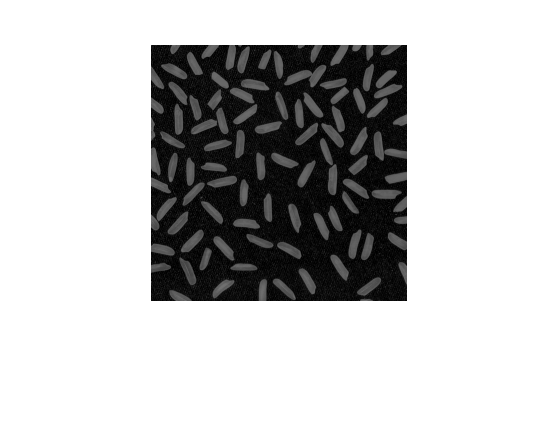


I2 = I - background;
imshow(I2);

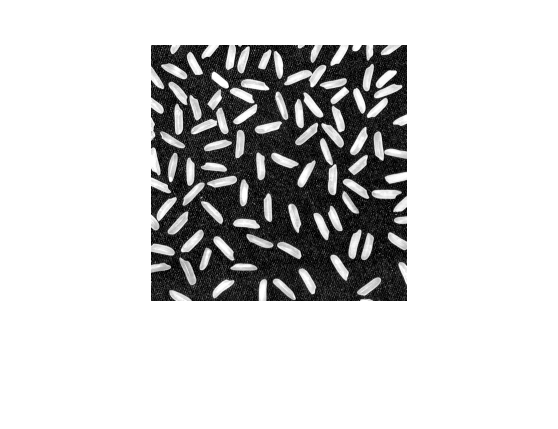


I3 = imadjust(I2);
imshow(I3);

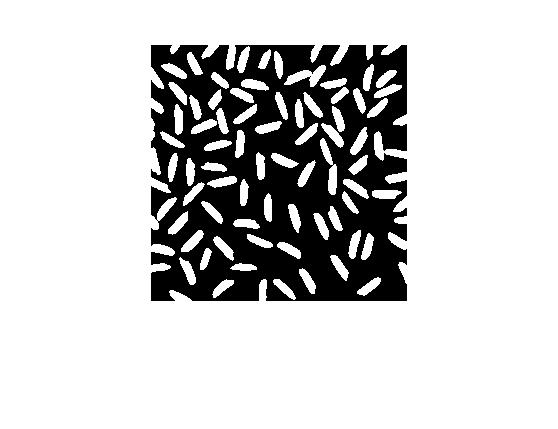


bw = imbinarize(I3);
bw = bwareaopen(bw,50);
imshow(bw);

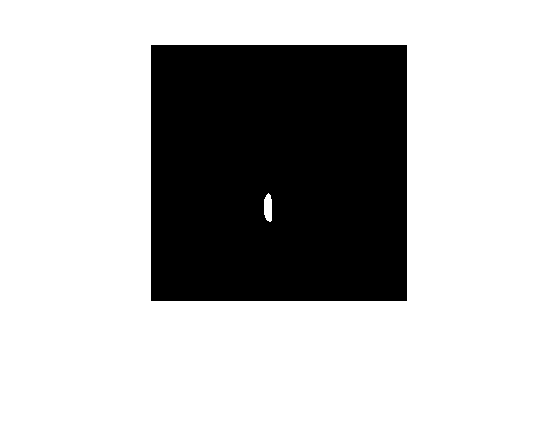


cc = bwconncomp(bw,4);
grain = false(size(bw));
grain(cc.PixelIdxList{50}) = true;
imshow(grain);

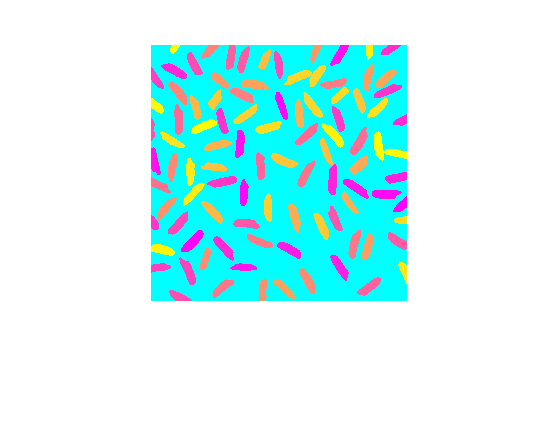


labeled = labelmatrix(cc);
RGB_label = label2rgb(labeled,'spring','c','shuffle');
imshow(RGB_label);

## coin

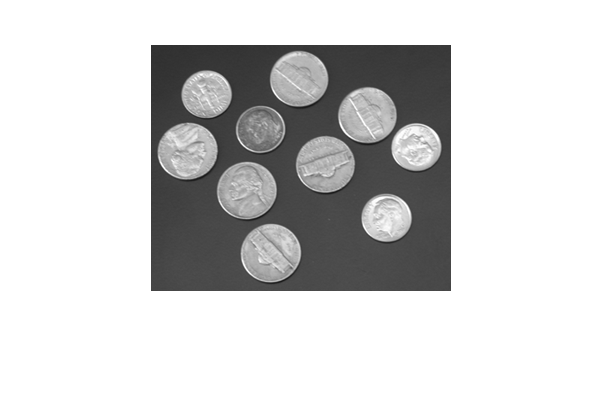

clear all; clc;

I = imread('./imdata/coins.png');
imshow(I);

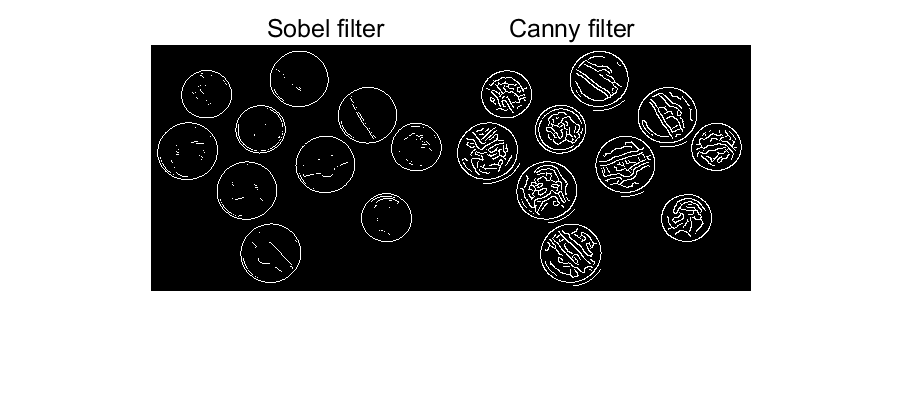


BW1 = edge(I,'sobel');
BW2 = edge(I,'canny');
figure;
imshowpair(BW1,BW2,'montage');
title('Sobel filter                  Canny filter');

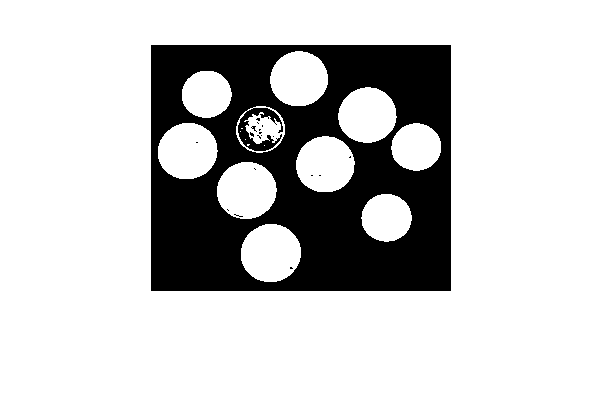


% BW = im2bw(I);
BW = imbinarize(I);
imshow(BW);

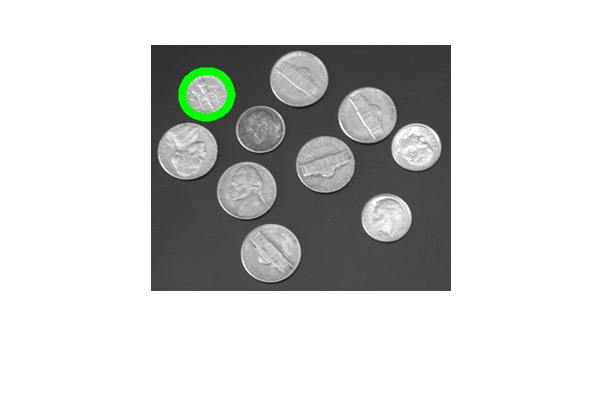

dim = size(BW);
col = round(dim(2)/2)-90;
row = find(BW(:,col), 1);
boundary = bwtraceboundary(BW,[row, col], 'N');
imshow(I);
hold on;
plot(boundary(:,2),boundary(:,1),'g','LineWidth',3);


BW_filled = imfill(BW,'holes');
boundaries = bwboundaries(BW_filled);


## circular objects

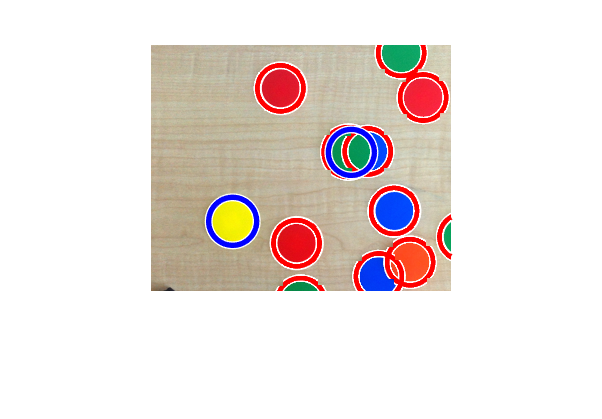

clear all; clc;
rgb = imread('./imdata/coloredChips.png');
imshow(rgb);

gray_image = rgb2gray(rgb);
imshow(gray_image);
[centers, radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','dark', ...
    'Sensitivity',0.9);

imshow(rgb);
h = viscircles(centers, radii);

[centers, radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','dark', ...
    'Sensitivity',0.9,'Method','TwoStage');
h2 = viscircles(centers,radii);

[centersBright, radiiBright] = imfindcircles(rgb,[20 25],'ObjectPolarity','bright', ...
    'Sensitivity',0.9,'Method','TwoStage');
h3 = viscircles(centersBright,radiiBright,'Color','b');

## Detecting cars

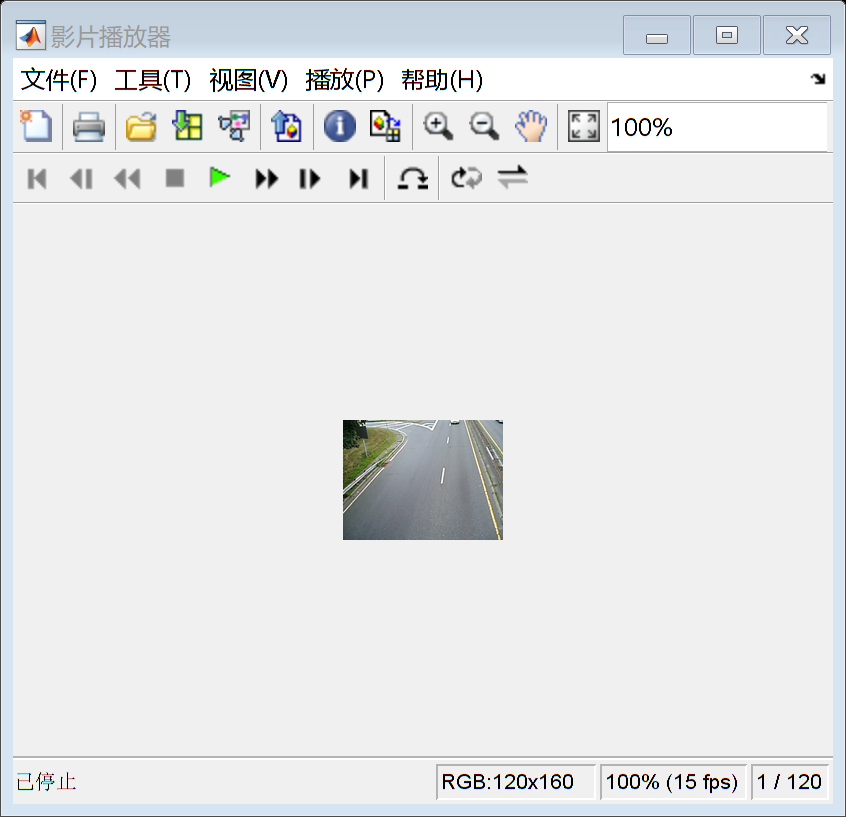

clear all; clc;

trafficVid = VideoReader('./imdata/traffic.mj2');
% implay('traffic.mj2');

darkCarValue = 50;
% darkCar = rgb2gray(read(trafficVid,71));
% noDarkCar = imextendedmax(darkCar, darkCarValue);
% imshow(darkCar);
% figure; imshow(noDarkCar);
sedisk = strel('disk',2);
% noSmallStructure = imopen(noDarkCar,sedisk);
% imshow(noSmallStructure);

nframes = trafficVid.NumFrames;
I = read(trafficVid,1);
taggedCars = zeros([size(I,1) size(I,2) 3 nframes],class(I));
for k = 1:nframes
    singleFrame = read(trafficVid, k);
    I = rgb2gray(singleFrame);
    noDarkCar = imextendedmax(I, darkCarValue);
    noSmallStructure = imopen(noDarkCar,sedisk);
    
    noSmallStructure = bwareaopen(noSmallStructure,150);
    taggedCars(:,:,:,k) = singleFrame;
    
    stats = regionprops(noSmallStructure, {'Centroid','Area'});
    width = 2;
    if ~isempty([stats.Area])
        areaArray = [stats.Area];
        [junk,idx] = max(areaArray);
        c = stats(idx).Centroid;
        c = floor(fliplr(c));
        row = c(1)-width:c(1)+width;
        col = c(2)-width:c(2)+width;
        
        taggedCars(row,col,1,k) = 255;
        taggedCars(row,col,2,k) = 0;
        taggedCars(row,col,3,k) = 0;
    end
end
frameRate = trafficVid.FrameRate;
% implay(taggedCars,frameRate);